# **Session 2: Analysis of the frequency response of a digital control system**

The practices of the Automatic Control subject consist in the study of a servomechanism of angular positioning (LJ Technical Systems) controlled by a PC. The laboratory sessions P1 and P2 focus on the experimental analysis of the temporal and frequency responses of the system, respectively. Sessions P3 and P4 are dedicated to the design of PID controllers. Finally, in session P5 controllers will be designed in the frequency domain.

**OBJETIVE: Analysis of the frequency response of the digital velocity control system. Analysis of the stability by the Nyquist criterion.**

**In this session the student must:**

- **Experimentally find the frequency response of the system in open loop.**

- **Apply the Nyquist criterion to determine the range of values of a proportional controller so that the closed-loop system is stable, and verify it experimentally.**

- **Compare the results obtained with the theoretical results.**

% Alternate between the experiment data and the directory Results
% If you want to use the data in the directory Results = false
% If you want to use your own data = true
useExperimentalData = false;

# Exercise 7: Obtain the Nyquist diagram

Using the values of the model of the practice 1 represent in the same diagram the frequency response of the:

- The open-loop velocity system in continuous time.

- The open-loop velocity system with a sampling time of $T_s =0\ldotp 01s$.

- Identify the zones corresponding to high and low frequencies on the graphs.

- Justify the differences observed between the graphs in each of the frequency bands.

% Plant's parameters
K_mot=0.82; %[rpm/V]
T_mot=0.24; %seg

% Sampling time
Ts=0.01;

% Continuous and digital transfer functions of the model
F=tf([K_mot],[T_mot 1])


F =
 
     0.82
  ----------
  0.24 s + 1
 
Continuous-time transfer function.



Fd=c2d(F,Ts)


Fd =
 
   0.03346
  ----------
  z - 0.9592
 
Sample time: 0.01 seconds
Discrete-time transfer function.



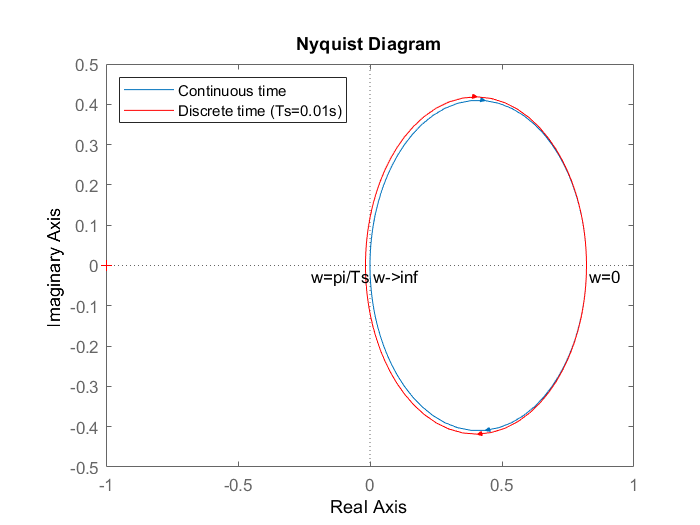

% Nyquist diagrams
figure
nyquist(F)
hold on 
nyquist(Fd,'red')
legend('Continuous time',strcat('Discrete time ',strcat(strcat(' (Ts=',num2str(Ts)),'s)')),'location','NorthWest');
text(dcgain(F)+0.010,-0.025,'w=0');
text(real(freqresp(Fd,pi/Ts))-0.205,imag(freqresp(Fd,pi/Ts))-0.025,'w=pi/Ts');
text(freqresp(F,inf)+0.010,freqresp(F,inf)-0.025,'w->inf');  

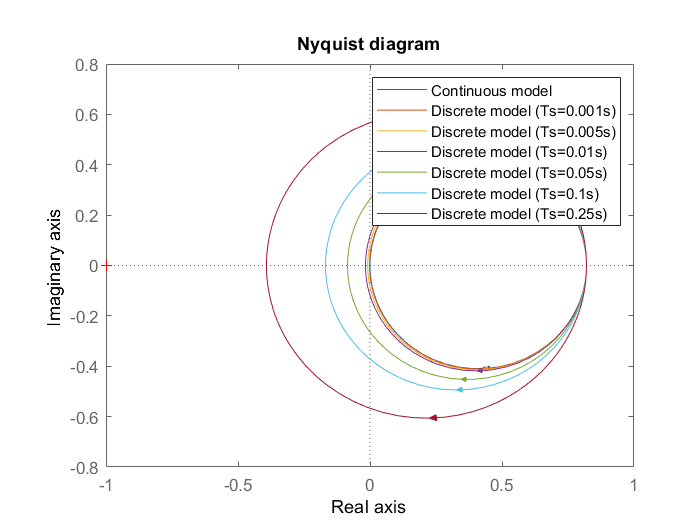

% We visualize the Nyquist for different sampling periods
    i=1;
    Ts=[0.001 0.005 0.01 0.05 0.1 0.25];
    [fils cols]=size(Ts);
    legenda={'Continuous model'};
    while (i<=cols)
        legenda={char(legenda);strcat(strcat('Discrete model (Ts=',num2str(Ts(1,i))),'s)')};
        i=i+1;
    end
    legenda=char(legenda);
    figure(2);
    nyquist(F);
    hold on;
    %legend('model continu');
    i=1;        
    while (i<=cols)
        nyquist(c2d(F,Ts(1,i),'zoh'));
        % legend(strcat(strcat('model discret(Ts=',num2str(Ts(1,i))),'s)'));
        i=i+1;
    end
    legend(legenda);
    title('Nyquist diagram');
    xlabel('Real axis');
    ylabel('Imaginary axis');

As it can be seen, the higher the Ts, the closer the diagram to the critical point (-1.0), which means the system is more unstable.

# Exercise 8: Experimentally obtaining the Nyquist diagram of the discrete system

Open and execute the model P2_Ex8.slx. Generate a sinusoidal signal input of amplitude 2V and frequency 0.25Hz. Measure the gain and offset of the output signal. Repeat the process for the frequencies of 0.5, 0.8, 1, 2, 4, 5, 10, 20 and 50Hz. Use a sampling period of 0.01 seconds.


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



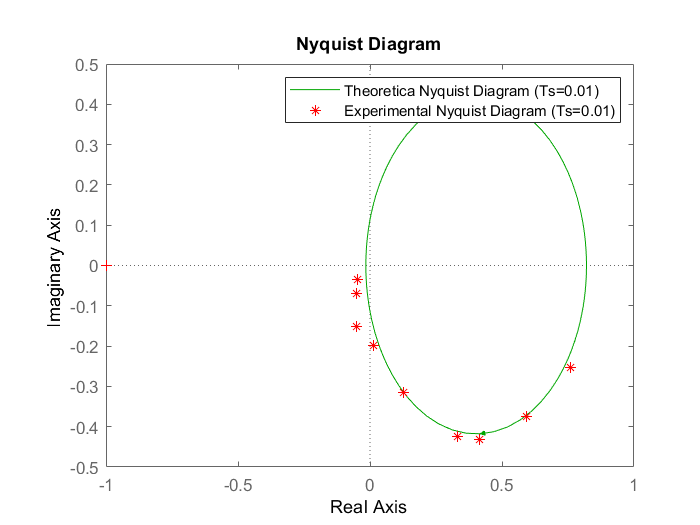

if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'E2']);
    open P2_Ex8.slx
    run P2_Ex8.slx;
else
    % Vector of experimental gains
    G=[0.8 0.7 0.6 0.54 0.34 0.2 0.16 0.085 0.06];
    % Vector of experimental phase shifts (in radians)
    F=[18.45 32.4 46.08 52 68.4 86.4 108 126 144]*(-pi/180);
    % Calculation of the complex in Cartesian form
    X=real (G.*exp(F*j));
    Y=imag(G.*exp(F*j));
    
    % Introduction of plant parameters
    K0=0.82;
    tau0=0.26;
    planta=tf([K0],[tau0,1])
    
    % Discrete time model
    Ts=0.01;
    plantad=c2d(planta,Ts,'zoh');
    
    % Plotting the theoretical and experimental Nyquist diagram
    figure
    nyquist(plantad,'g')
    hold on
    plot(X,Y, 'r*' )
    legend('Theoretica Nyquist Diagram (Ts=0.01)','Experimental Nyquist Diagram (Ts=0.01)')

end

As we can see, the experimental Nyquist diagram resembles the theoretical one. The small differences come from the errors of calculations, since the higher the frequency, the smaller the samples and the more difficult is to measure the changes produced.

# Exercise 9: Application of the Nyquist criterion

Using the theoretical diagram, apply the Nyquist criteria to:

- Analyze the stability of the discrete time system.

- Find the range of values of the proportional controller $K_p$ that make the discrete time system in closed loop with velocity feedback stable.

Compare it to the case of continuous time by checking how the theoretical diagrams vary when increasing $K_P$. Verify the result by analyzing the step response to $K_P$=5 and for a value of $K_P$ out of range, both in simulation and experimentally.


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



Ts = 0.0100


sistema_discreto =
 
   0.03094
  ----------
  z - 0.9623
 
Sample time: 0.01 seconds
Discrete-time transfer function.



gain = -0.0158

Kp_limit = 63.4225

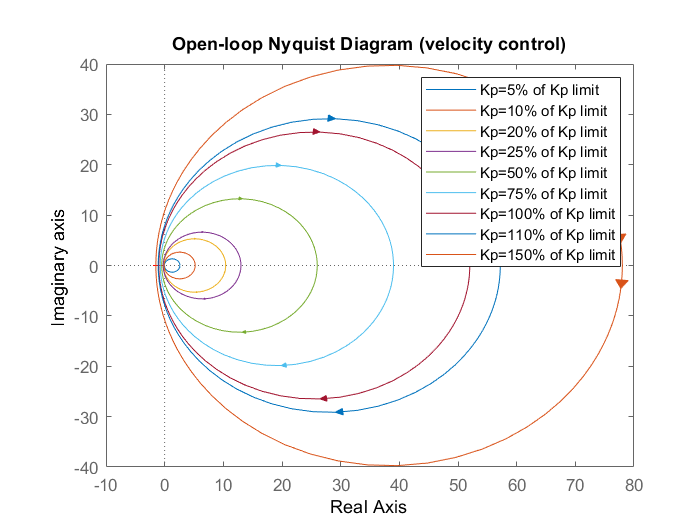

if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'E2']);
    open P2_Ex9b.slx;
    run P2_Ex9b.slx;
else
    % System's model (from the file of practice 1: exercise 4)
    K0=0.82;
    tau0=0.26;
    planta=tf(K0,[tau0 1])
        
    % Sampling time
    Ts=0.01
    Kp=sym('K');
    
    % Determination of the digital system
    sistema_discreto=c2d(planta,Ts,'zoh')
    
    % Determination of the Kp_limit
    gain=real(freqresp(sistema_discreto,pi/Ts))
    Kp_limit=-1/gain
    
    
    % Kp_limit percentages
    vector=[5 10 20 25 50 75 100 110 150];
    vector=[vector; vector*Kp_limit/100];
    [fils cols]=size(vector);
    i=1;
    figure
    hold on;
    
    while (i<=cols)
        if (vector(1,i)<100)
            nyquist(sistema_discreto*vector(2,i));
        elseif (vector(1,i)==100)
            nyquist(sistema_discreto*vector(2,i));
        else
            nyquist(sistema_discreto*vector(2,i));
        end
        if (i==1)
            legenda={strcat(strcat('Kp=',num2str(vector(1,i))),'% of Kp limit')};
        else
            legenda={char(legenda);strcat(strcat('Kp=',num2str(vector(1,i))),'% of Kp limit')};        
        end
        i=i+1;
    end
    legenda=char(legenda);
    legend(legenda);
    title('Open-loop Nyquist Diagram (velocity control)');
    xlabel('Real Axis');
    ylabel('Imaginary axis');
end

As can it be seen, the higher the Kp, the bigger the Nyquist diagram, with which the system becomes more unstable. 

# Exercise 10: Obtaining the theoretical Bode diagram

Using the system model and the bilinear transformation $\textrm{d2c}\left(\ldotp \ldotp \ldotp ,\textrm{'Tustin'}\right)$, graphically plot the Bode diagram and determine the gain margin and the phase margin from this diagram. Relate the gain margin with the critic $K_P$ of the previous section.

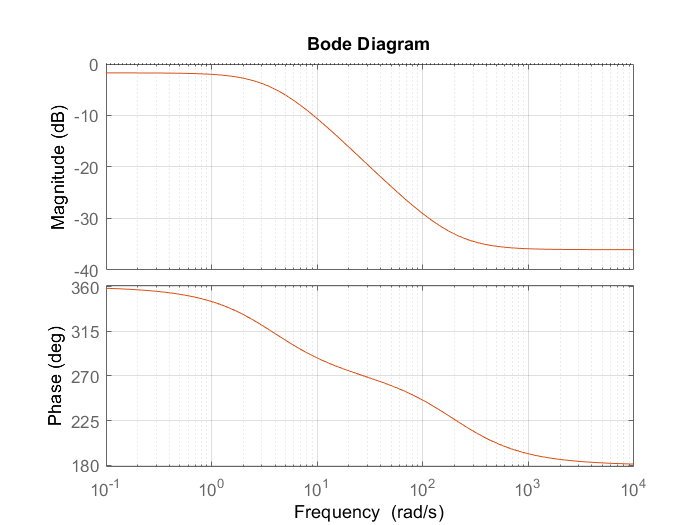

clc;
close all;
clear all;
% System model (we open file created in practice 1: exercise 4)
    K0=0.82;
    tau0=0.26;
    Kt=0.017;
    planta=tf([K0],[tau0 1]);
    
% Sampling period
Ts=0.01;

% Theoretical system
sistema_discreto=c2d(planta,Ts,'zoh');
sistema_bilineal=d2c(sistema_discreto,'tustin');

% Image of the Bode phase / gain margins
figure(1);
bode(sistema_bilineal);
hold on;
grid on;
[Gm,Pm,Wcg,Wcp]=margin(sistema_bilineal);
margin(sistema_bilineal);
title('Bode Diagram');

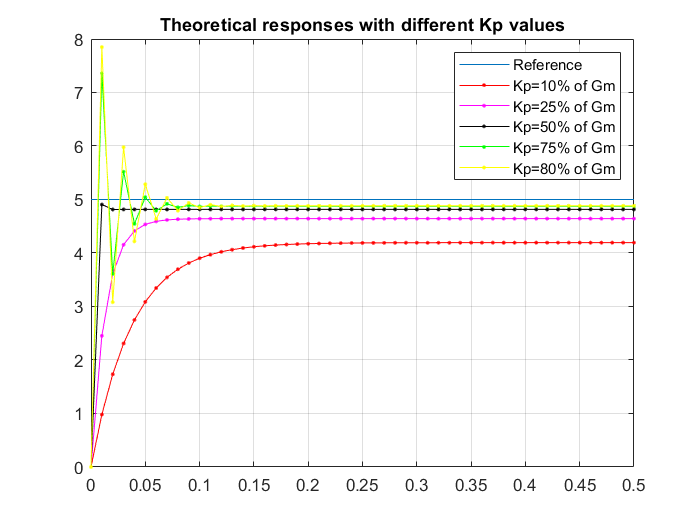

Vmax=5;
% Define a time interval
Tx=0.0:Ts:50*Ts;
% Define reference (step of Vmax of height)
X =[Vmax*ones(size(Tx))];
% Define a set of Kp's with which we want to simulate the system,
% expressed as a percentage of Gm (or Kp_max)
Kp=[10 25 50 75 80]';
Kp=[Kp (1/100)*Kp*Gm];
% Simulate the behavior of the system for different Kp's
[fils cols]=size(Kp);
i=1;
% The vector Y stores the responses of the system to the step 
% with different constants of proportionality

Y=[];
while (i<=fils)
    % the model_discret (...) function contains a closed-loop
    % system modeling and proportional controller
    Y=[Y; Kt*model_discret(0,K0/Kt,Kp(i,2),Kt,tau0,Ts,X)];
    i=i+1;
end

figure(2);
T_MAX=max(Tx);
T_MIN=min(Tx);
Y_MAX=max(max(Y));
Y_MIN=min(min(Y));

% Draw the reference
plot(Tx,X);
hold on;
grid on;
% Draw system simulations
i=1;
styles=['r.-';'m.-';'k.-';'g.-';'y.-';'c.-'];
[sty_fil sty_col]=size(styles);
legenda={'Reference'};
while (i<=fils)
    plot(Tx,Y(i,:),styles(mod(i,sty_fil),:));
    legenda={char(legenda);strcat(strcat('Kp=',num2str(Kp(i,1))),'% of Gm')};
    i=i+1;
end
title('Theoretical responses with different Kp values');
legenda=char(legenda);
legend(legenda);

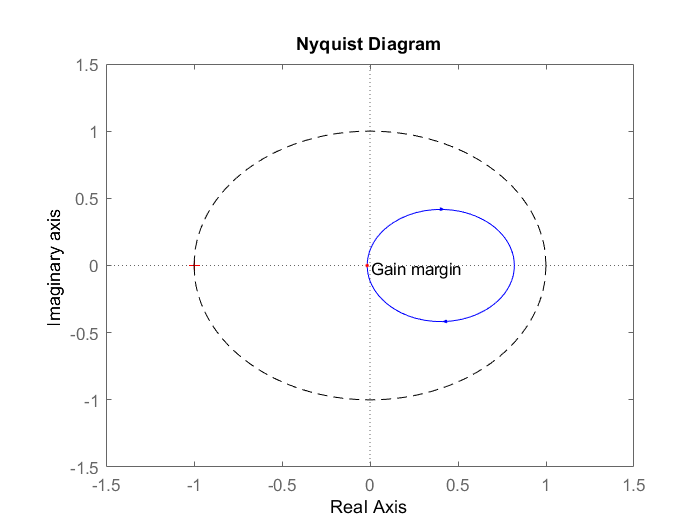

% Discrete system's Nyquist
figure(3);
hold on;
nyquist(sistema_discreto,'b-');
freq_resp=freqresp(sistema_discreto,Wcp);
point=[real(freq_resp) imag(freq_resp)];

% Draw the point corresponding to the margin of phase and profit margin
text(point(1,1)+0.02,point(1,2)-0.02,'Phase margin');
plot(point(1,1),point(1,2),'r.');
freq_resp=freqresp(sistema_discreto,pi/Ts);
point=[real(freq_resp) imag(freq_resp)];
text(point(1,1)+0.02,point(1,2)-0.02,'Gain margin');
plot(point(1,1),point(1,2),'r.');
axis([-1.5 1.5 -1.5 1.5]);
title('Nyquist Diagram');
xlabel('Real Axis');
ylabel('Imaginary axis');
x=[0 point(1,1)]';
y=[0 point(1,2)]';
circumf;